# **ECON 310: Dynamic Macroeconomics**

### **Problem Set 2**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

Consider the life cycle model with borrowing constraints, where the representative household lives up to age T −1. It works and receives exogenous labor income, yt, for the first tr −1 years of life, and then retires and receives a pension, κytr−1, from age tr to T − 1 where 0 < κ < 1 and ytr−1 is the household's labor income in the last year of working life. It maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. The optimization problem is


$$\underset{\{c_t\}_{t=0}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} U =  \mathbb\sum_{t=0}^{T-1} \beta^{t} \frac{c_t^{1-\gamma}}{1-\gamma} \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\mathbb {G_t}\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq0 \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


where |ρ| < 1, Gt is age-specific average of income, ϵt ∼ N(0, σ2), and the initial wealth endowment, a0 ≥ 0, is given.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\khuct\Downloads\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\khuct\Downloads\Matlab 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.

Loading VHLSS data...
  Loading household member data (muc123a)...
  Loading income data (muc4a)...


par = model.gen_grids(par); % Generate the state space.

## Plot income profile from VHLSS data

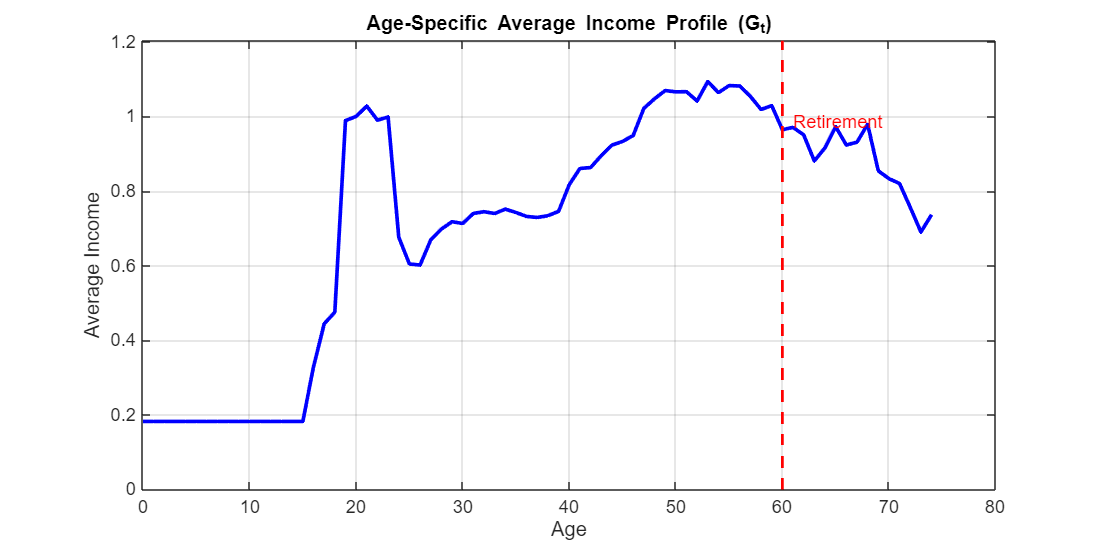

my_graph.plot_income_profile(par);

## Solve the baseline model

fprintf('Step 3: Solving baseline model (beta = %.2f, gamma = %.2f)...\n', par.beta, par.sigma);

Step 3: Solving baseline model (beta = 0.94, gamma = 2.00)...


sol = solve.lc(par);

------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem Solved------------


fprintf('Baseline model solved successfully.\n\n');

Baseline model solved successfully.



## Simulate the model and plot the policy functions.

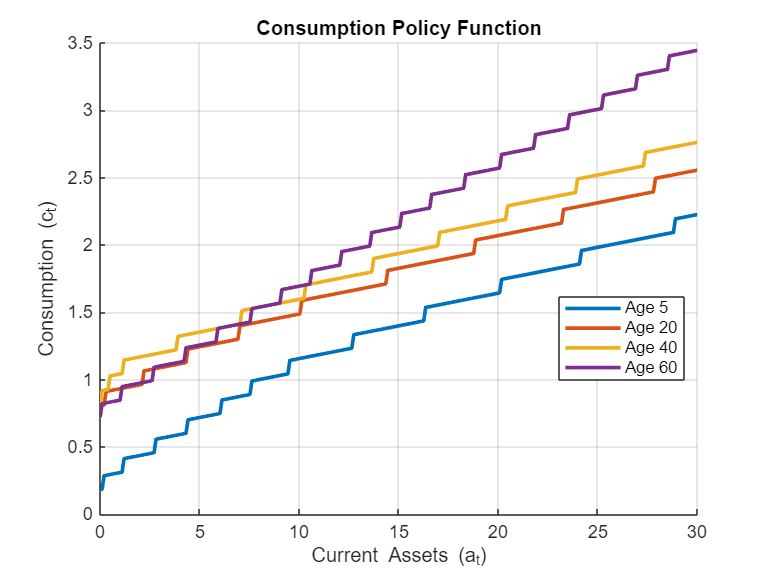

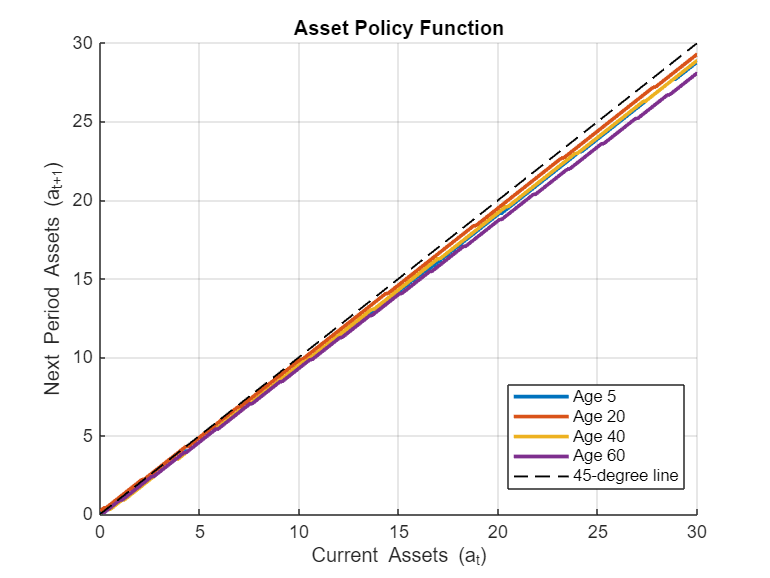

sim = simulate.lc(par,sol); % Simulate the model.
my_graph.plot_policy_functions(par, sol);

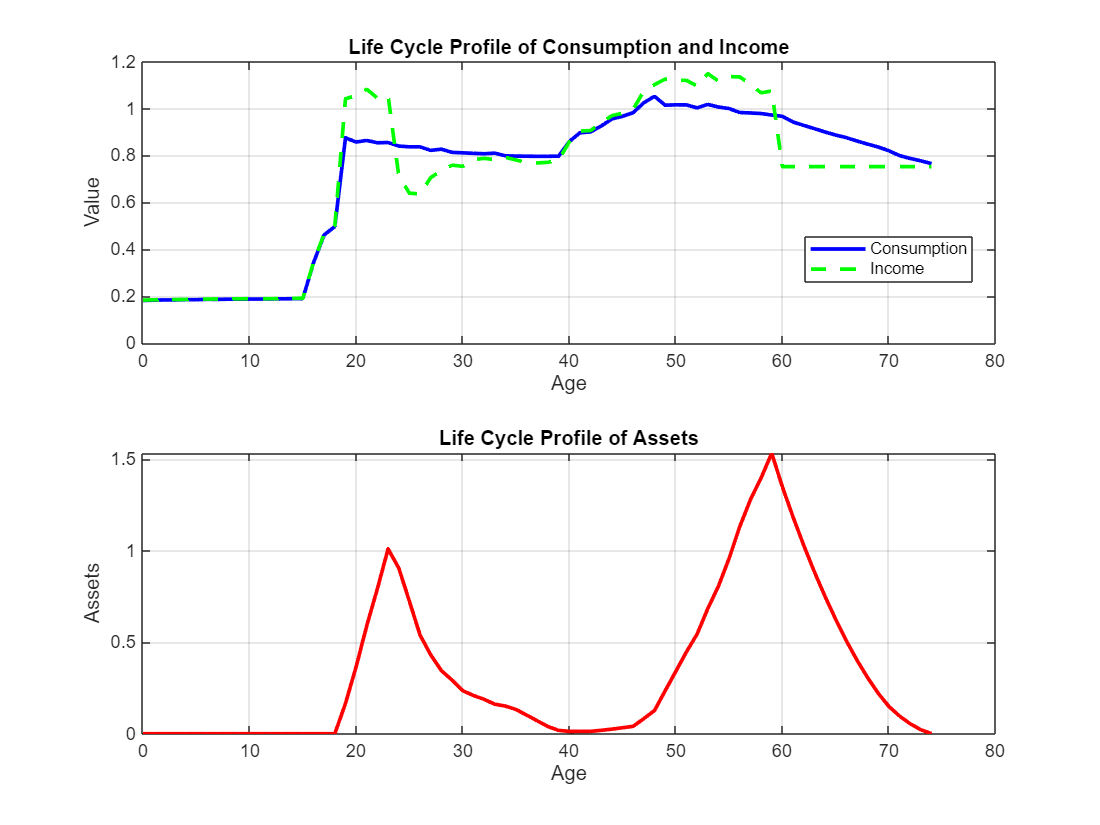

my_graph.plot_lifecycle_profiles(sim);

## Solve and simulate for parameter variations

sol_collection = solve.lc_param_variations(par);

Solving model for 16 parameter combinations...
Solving combination 1/16: beta = 0.90, gamma = 2.00
------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem Solved------------
Solving combination 2/16: beta = 0.90, gamma = 3.00
------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem Solved------------
Solving combination 3/16: beta = 0.90, gamma = 4.00
------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age:

param_results = simulate.param_variations(par, sol_collection);

Simulating for different beta values with gamma = 2.00...
  Simulating for beta = 0.90
  Simulating for beta = 0.92
  Simulating for beta = 0.94
  Simulating for beta = 0.96
Simulating for different gamma values with beta = 0.96...
  Simulating for gamma = 2.00
  Simulating for gamma = 3.00
  Simulating for gamma = 4.00
  Simulating for gamma = 5.00
Creating data for average wealth heat map...


fprintf('Step 8: Creating parameter variation plots...\n');

Step 8: Creating parameter variation plots...


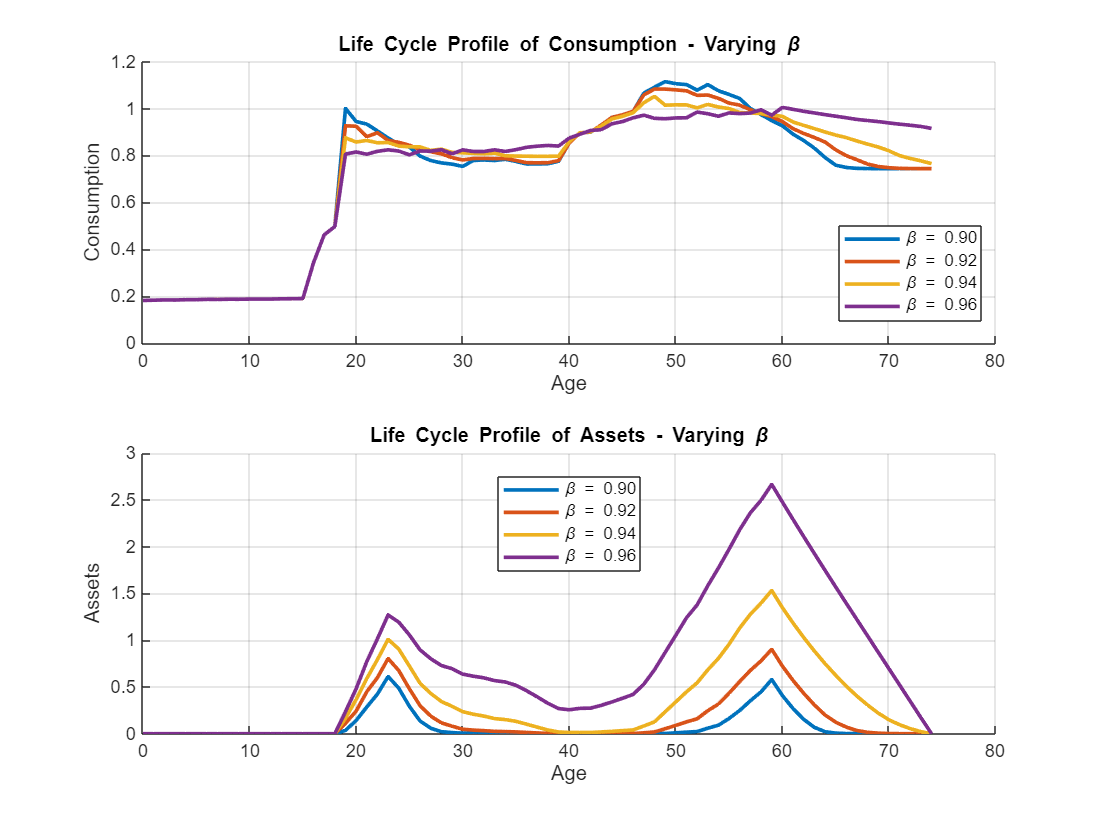

my_graph.plot_beta_variations(sim.ages, param_results.c_profiles_beta, ...
    param_results.a_profiles_beta, param_results.beta_values);

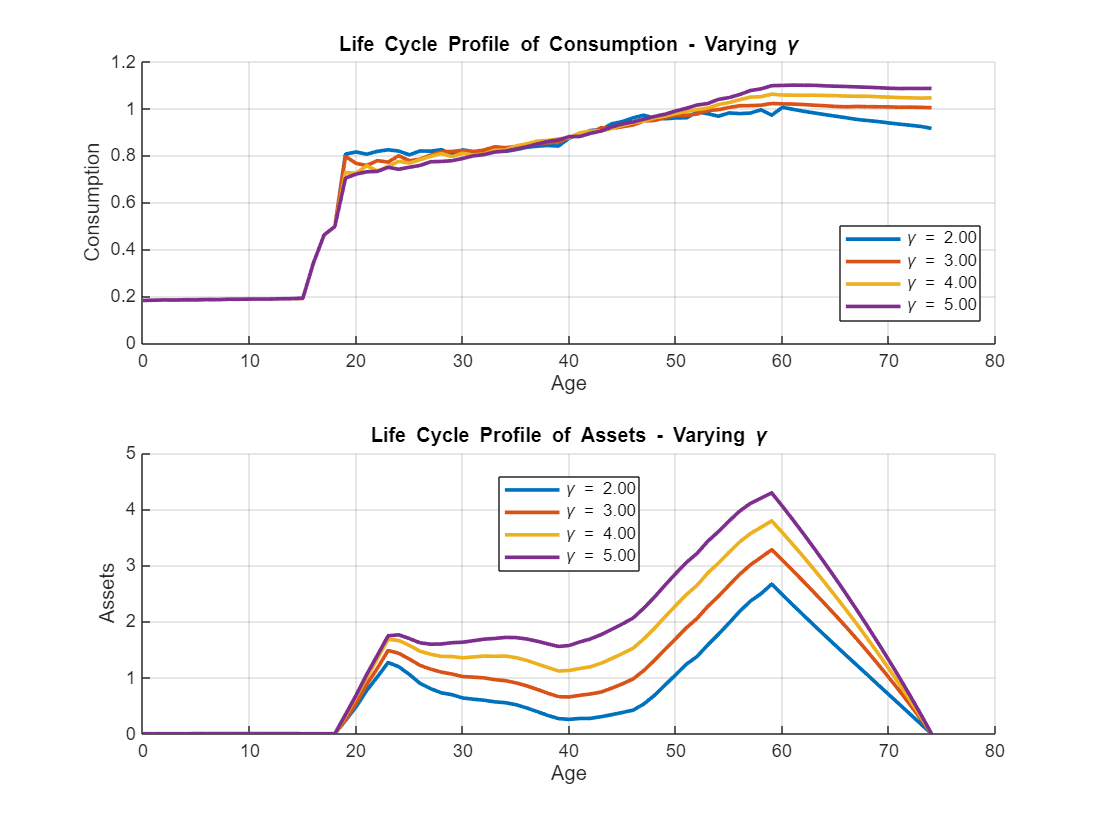

my_graph.plot_gamma_variations(sim.ages, param_results.c_profiles_gamma, ...
    param_results.a_profiles_gamma, param_results.gamma_values);

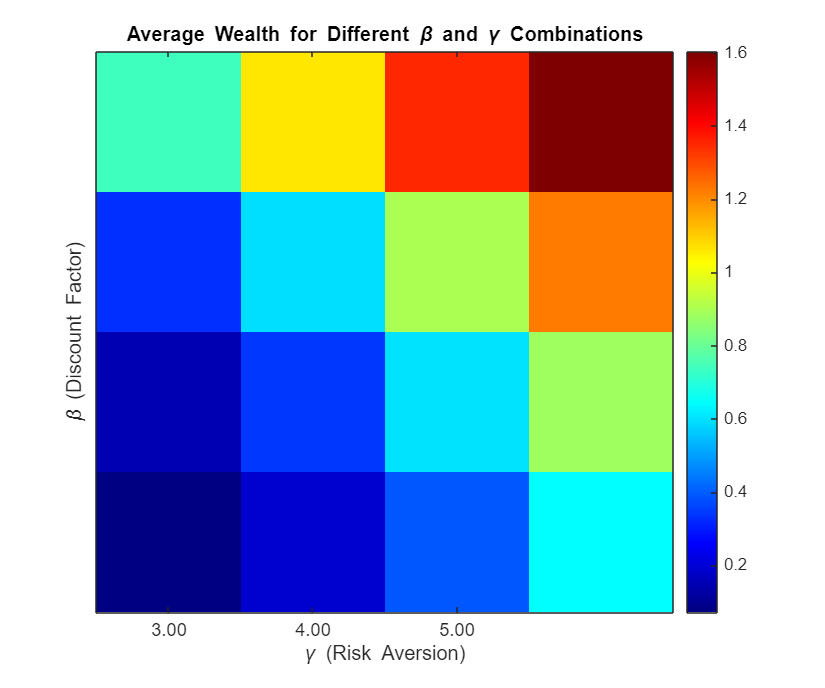

my_graph.plot_wealth_heatmap(param_results.beta_values, param_results.gamma_values, ...
    param_results.avg_wealth);